s = tf("s");

%
H = 20*(0.3*s+1)/(0.4*s+1)/(2*s+1)/(1.5*s+1)


H =
 
            6 s + 20
  -----------------------------
  1.2 s^3 + 4.4 s^2 + 3.9 s + 1
 
Continuous-time transfer function.



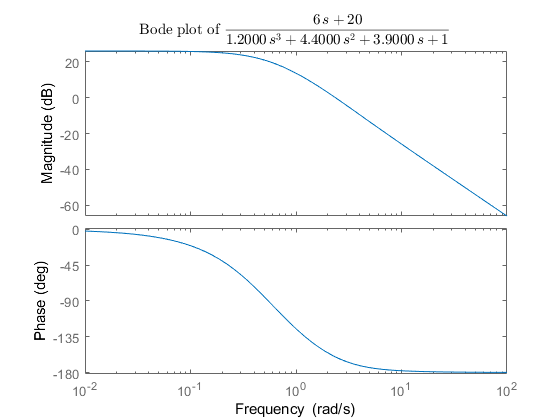

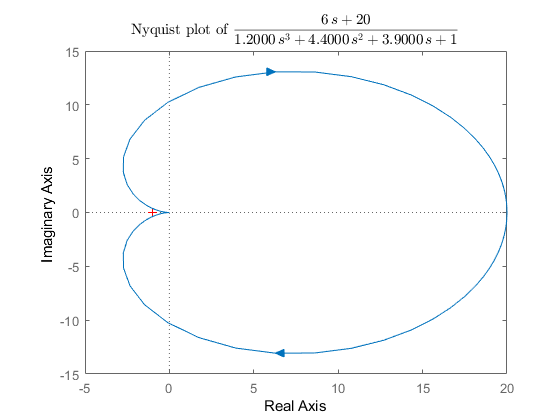

plot_all_and_save(H)

function plot_all_and_save(H)
    syms s;
    [num, den] = tfdata(H);
    sym_H = poly2sym(sym(num), s) / poly2sym(sym(den), s);
    sym_title = latex(sym_H);
    %
    
    mkdir plots;
   
    figure;
    bode(H);
    title(sprintf("Bode plot of $$ %s $$", sym_title), "Interpreter", "Latex");
    saveas(gcf, sprintf("plots/Bode of %s.jpg", strrep(sym_title, '\', '')));
    
    figure;
    nyquist(H);
    title(sprintf("Nyquist plot of $$ %s $$", sym_title), "Interpreter", "Latex");
    saveas(gcf, sprintf("plots/Nyquist of %s.jpg", strrep(sym_title, '\', '')));
end